# Inverse Kinematics Algorithm

## Modeling and Control of Robotic Manipulators

#### Code to switch between the different cases in the tasks

mode='varJ';    % 3)
% mode='invKin';    % 5)
% mode='invKinDamped';  % 9)
% mode='invKinRedundant'; % 10-11)

disp(['inverse kinematics algorithm : ' mode]);

inverse kinematics algorithm : varJ


#### Sawyer

Load the Sawyer kinematic model with `importrobot`. For sake of clarity remove redundant body parts. Set the z-offset of the reference trajectory to zero and regenerate the reference trajectory for the Sawyer arm

robot=importrobot('sawyer.urdf');

% remove obsolete joints and bodies
robot.removeBody('head');
robot.removeBody('right_arm_itb');
robot.removeBody('right_hand_camera');
robot.removeBody('right_torso_itb');
robot.removeBody('right_wrist');
eeframename='right_hand'; % name of end effector frame for forward kinematics
dof=7; % degrees of freedom
K=5.0*eye(6); % gain matrix
lambdasqr=0.05*eye(dof); % damping factor for inverse kinematics algorithm with damped least squares

#### Follow the same steps (1-9) for the Sawyer robot

#### 1. Load Reference Trajectory

Load the reference trajectory with `load 'TrajectorySawyer.mat'` and plot it with `plotTaskSpaceTrajectory`. 

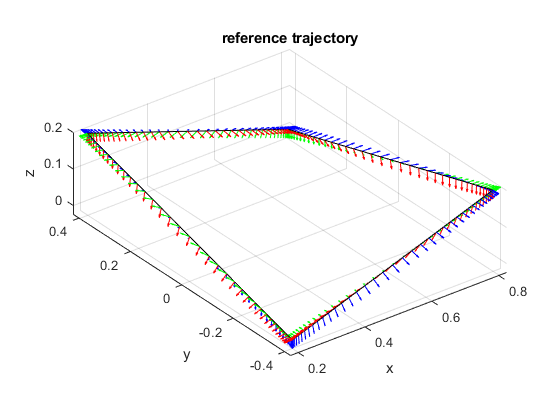

load 'TrajectorySawyer.mat';

figure(1);
plotTaskSpaceTrajectory(tformxd);
title('reference trajectory');

tformx=zeros(4,4,length(t));
poseerror=zeros(6,length(t));
q=zeros(dof,length(t));  % joint configuration
qdot=zeros(dof,length(t));  % joint velocities
qdotnull=zeros(dof,length(t));  % null space joint velocities   % 12)
e=zeros(6,length(t));  % orientation and pose error
w=zeros(1,length(t)); % volume of manipulation ellipsoid
condJ=zeros(1,length(t)); % condition number of Jacobian

#### 2. Determine initial joint configuration

Determine the joint configuration *confq0* that corresponds to the initial reference pose *tformxd(:,:,1)* using the inverse kinematics solver `robotics.InverseKinematics` (see lab on Inverse Kinematics).

*confq0* determines the initial pose *q(:,1)* of the resolved rate motion control. The array *tformx(:,:,k)* retains the transforms of the actual end effector frame at time instances *k*.

% setup inverse kinematics solver
ik = robotics.InverseKinematics('RigidBodyTree', robot);
% Disable random restart to ensure consistent IK solutions
ik.SolverParameters.AllowRandomRestart = false;
% Specify weights for the tolerances on each component of the goal pose.
weights = ones(6,1);
% determine initial joint configuration from inverse kinematics solver
initialguess=JointVec2JointConf(robot,[0 0 0 pi/2 0 0 0]);
confq0=ik(eeframename, tformxd(:,:,1), weights, initialguess);

% map angle to interval [-pi, pi]
q(:,1) = wrapToPi(JointConf2JointVec(confq0));
confq0=JointVec2JointConf(robot,q(:,1));

disp(['initial joint configuration:' mat2str(q(:,1)',3)]);

initial joint configuration:[-1.48 -0.576 0.00606 2.19 0.124 -0.041 0.148]


tformx(:,:,1)=robot.getTransform(confq0,eeframename);

% check for feasibility of initial pose
if (norm(tformxd(:,:,1)-tformx(:,:,1)) > 1e-2)
    disp(['initial configuration infeasible']);
    disp(['target pose: ' mat2str(tformxd(:,:,1))]);
    disp(['inverse kinematics solution : ' mat2str(tformx(:,:,1))]);
    disp(['error norm : ' num2str(norm(tformxd(:,:,1)-tformx(:,:,1)))]);
    return;
end


### Code for the tasks 3, 4, 5, 9, 10 and 11

Add your solution for assignement 3, 4, 5, 9, 10 and 11 in the given code structure

% mode openloop with constant or varying Jacobian, or inverse
% kinematic control scheme

for k=1:length(t)-1
    
    % calculate generalized pose error  % 4)    
    e(:,k)=robotics.manip.internal.IKHelpers.poseError(tformxd(:,:,k), robot.getTransform(JointVec2JointConf(robot,q(:,k)),eeframename));
    
    % calculate geometric Jacobian (due to angle-axis/quaternion representation)
    J=robot.geometricJacobian(JointVec2JointConf(robot,q(:,k)),eeframename);
    condJ(k)=cond(J); % calculate condition number ratio lambda_n/lambda_1
    eps=0.1;
    qeps=q(:,k)+eps*eye(dof); % offset vector for gradient calculation (f(q+eps)-f(q))/eps
    
    for i=1:dof
        % 11)
        gradw(i)=-(cond(robot.geometricJacobian(JointVec2JointConf(robot,qeps(:,i)),eeframename))-condJ(k))/eps;        
    end
    
    switch mode
        
        case 'varJ' % 3)
            % Open-loop control with varying jacobian (w.r.t. current configuration q)
            % resolved rate motion control with J(q_k)
            qdot(:,k)=J\xdotd(:,k);
            
            
        case 'invKin'   % 5)
            % Feedback control with inverse kinematics algorithm
            % poseerror [wx wy wz ex ey ez]
            % pose error orientation part from quaternion
            % equation (3.91) Siciliano
            % inverse kinematic control law dotq = J^(-1)(q)(dot xd + K e)
            qdot(:,k)=J\(xdotd(:,k) + K*e(:,k));
            
            
        case 'invKinDamped' % 9)
            % Feedback control with inverse kinematics algorithm with damping term
            % inverse kinematic control law dotq = (J^T J + lambda^2 I)^(-1)(J^T(dot xd + K e))
            qdot(:,k)=(J'*J + lambdasqr)\(J'*(xdotd(:,k) + K*e(:,k)));
            
        case 'invKinRedundant'
            % Feedback control with inverse kinematics algorithm for redundant arm
            % inverse kinematic control law dotq = J^dagger(q)(dot xd + K e) + (I_n - J^dagger J) dot q_0)
            eta=0.1;
            qdotnull(:,k)=(eye(dof) - pinv(J)*J)*gradw'*eta;    % 11)
            qdot(:,k)=pinv(J)*(xdotd(:,k) + K*e(:,k))+ qdotnull(:,k);   % 10)
            %qdot(:,k)=(J'*J + lambdasqr)\(J'*(xdotd(:,k) + K*e(:,k)))+ qdotnull(:,k);
    end
    q(:,k+1)=wrapToPi(q(:,k)+qdot(:,k)*deltat); % simple integrator
    tformx(:,:,k+1)=robot.getTransform(JointVec2JointConf(robot,q(:,k+1)),eeframename);
end

e(:,end)=robotics.manip.internal.IKHelpers.poseError(tformxd(:,:,end), tformx(:,:,end));


#### 3. Differential Kinematics

Reuse the code for resolved rate motion control of the lab on Differential Kinematics based on the difference equation 


$$\mathbf{q}_{k+1} = \mathbf{q}_{k} + \mathbf{J}(\mathbf{q_k})^{-1} \dot{\mathbf{x}}_k \Delta t $$


for the same constant velocity motion to track the reference trajectory in open loop mode ($$t \in [0, 8]$$ seconds). The vector of reference velocities  $$\dot{\mathbf{x}}_k$$ is provided in the array *xdotd(:,k)*.  The loop iterates through the sequence of time stamps to calculate the joint velocity *dotq(:,k)* according to the inverse kinematic control laws and then integrates the joint states from *q(:,k)* to *q(:,k+1)*.

#### 4. Calculate the pose error

Augment the code to implement the inverse kinematic control with quaternion error.

For each iteration:

Calculate the position error $$\mathbf{e}_p$$ between reference frame and current robot frame with help of `getTransform` and `tform2trvec`. Calculate the quaternions of reference frame $$ \mathcal{Q}_d$$ and end effector frame  $$\mathcal{Q}_e$$  with help of `getTransform` and `tform2quat`. Caluclate the orientation error $$\mathbf{e}_o$$ either according to Eq. (25) using ordinary vector operations or directly by  Eq. (24) utilizing the quaternion class with methods `inverse `and `vector` to extract the vector part of quaternion $$\Delta \mathcal{Q}$$.


$$\dot{\mathbf{e}} =\left\lbrack \begin{array}{c}
{\dot{\mathbf{e}} }_o \\
{\dot{\mathbf{e}} }_p 
\end{array}\right\rbrack$$


(Notice, that for Jacobians in ROS and the Robotics system toolbox the total error defines position and orientation error in reverse order.)

#### 5. Inverse Kinematic Control

Implement the control law for inverse kinematic control with quaternion error according to (26)


$$\dot{\mathbf{q}_{k}} = \mathbf{J}(\mathbf{q_k})^{-1} ( \dot{\mathbf{x}}_{d_k} + \mathbf{K} \mathbf{e}_k )
$$


Use a 6-by-6 identity gain matrix $$\mathbf{K}=\mathbf{I}$$. Notice, that you can use the left array division operator `\`  to solve


$$\mathbf{J}(\mathbf{q_k}) \dot{\mathbf{q}_{k}} =  ( \dot{\mathbf{x}}_{d_k} + \mathbf{K} \mathbf{e}_k )
$$


rather than to explicitly calculate the inverse Jacobian $$\mathbf{J}(\mathbf{q_k})^{-1}$$.

#### 6. Plot the motion

Simulate the UR10 robot motion under inverse kinematic control with an Euler integration step $$\mathbf{q}_{k+1}= \mathbf{q}_{k} + 
\dot{\mathbf{q}}_{k} \Delta t$ 
$ and plot the reference motion for position and orientation (quaternion), the actual motion of position and orientation (quaternion) and position error $$\mathbf{e}_p$$ and quaternion orientation error $$\mathbf{e}_o$$ over time

as shown in Figure 3. Compare the errors with the open-loop resolved rate motion control law


$$\mathbf{J}(\mathbf{q_k}) \dot{\mathbf{q}_{k}} =  
\dot{\mathbf{x}}_{d_k} 
$$


(see assignment Differential Kinematics).

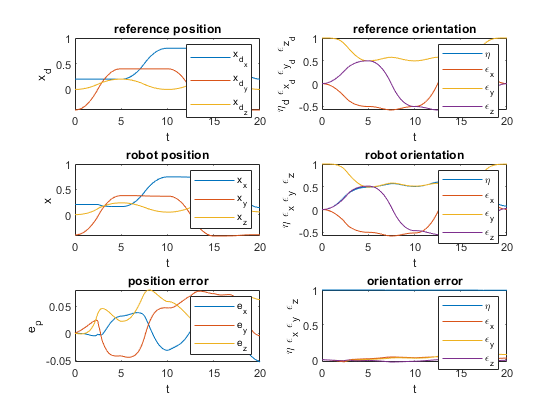

figure(2);
plotTaskSpaceError(t,tformx,tformxd);


disp(['final position error=' num2str(norm(e(1:3,end-1)),2)]);

final position error=0.16


disp(['final orientation error=' num2str(norm(e(4:6,end-1)),2)]);

final orientation error=0.082


#### 7. Report the position and orientation errors

Multiply the gain matrix  *K* by scalars $$\{0.1 , \ 1 ,\ 10 \}$$ and report the average (`mean`)  across the entire motion of position errors $$\mathbf{e}_p$$ and orientation errors $$\mathbf{e}_o$$ . Complete the table in the pdf-filefor the gains (K=0.1; K=1.0 and K=10.0).

disp(['average position error=' num2str(norm(mean(e(1:3,:),2)),2)]);

average position error=0.041


disp(['average orientation error=' num2str(norm(mean(e(4:6,:),2)),2)]);

average orientation error=0.065


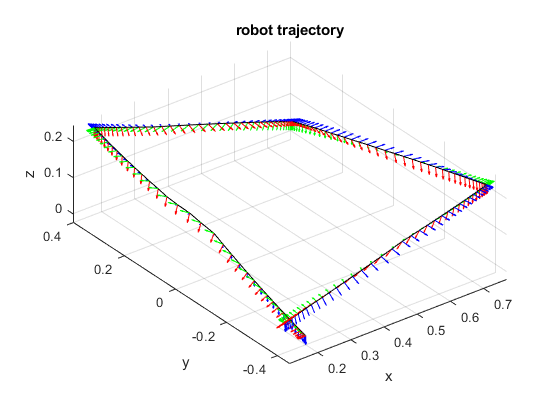


figure(3);
plotTaskSpaceTrajectory(tformx);
title('robot trajectory');

#### 8. Plot the joint velocities

Plot the vector of joint space velocities $$\dot{\mathbf{q}}$$ across the motion as shown in Figure 4 and report the maximum  (`max`) absolute joint velocities. Notice, that the reference trajectory along the first segment gets close to a singularity resulting in excessive joint velocities. Plot the condition number (`cond`) of the geometric Jacobian across the motion and observe the singularity.

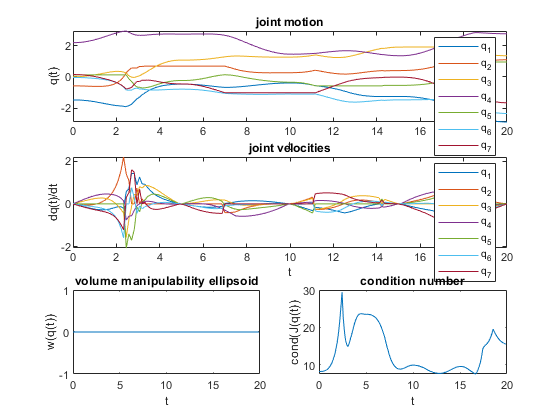

figure(4);
plotJointMotion(t,q,qdot,mode,w,condJ,qdotnull);


disp(['maximum absolute joint velocities= ' mat2str(max(abs(qdot),[],2)',2)]);

maximum absolute joint velocities= [1.4 2.2 1.6 0.75 2.1 1.6 1.6]


disp(['minimum manipulability ellipsoid volume=' num2str(norm(min(w)),2)]);

minimum manipulability ellipsoid volume=0


disp(['maximum condition number J=' num2str(norm(max(condJ)),3)]);

maximum condition number J=29.4


#### 9. Damped Inverse Kinematic Algorithm

Modify the control law to the damped inverse kinematics algorithm according to Eq. (15) with $$\lambda=0.05$$. Compare the average pose error and maximum joint velocities with the non-damped inverse kinematics algorithm.

#### 10. Inverse Kinematics for redundant manipulator

**optional:** Implement the control law for inverse kinematic control based on the pseudoinverse with quaternion error for the redundant manipulator Saywer according to Eq. (6). Set $$\dot{\mathbf{q}}_0$$ to zero. 

#### 11. Nullspace velocity

**optional: **Add a nullspace velocity in Eq. (6) to achieve a secondary objetive such that $$\dot{\mathbf{q}}_0$$ minimizes the condition number of the Jacobian $$\mathbf{J}$$ according to Eq. (11). Compare the maximum condition number and mean task space error for the pseudoinverse control law with and without secondary objective.